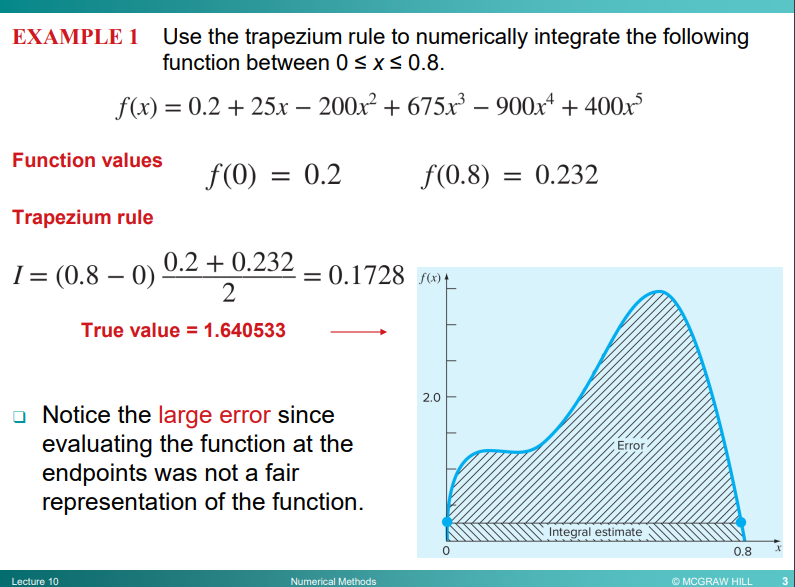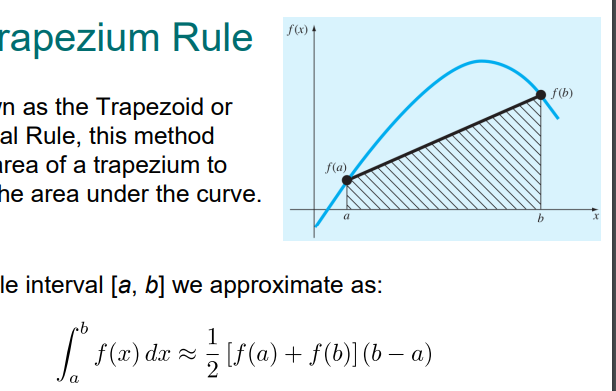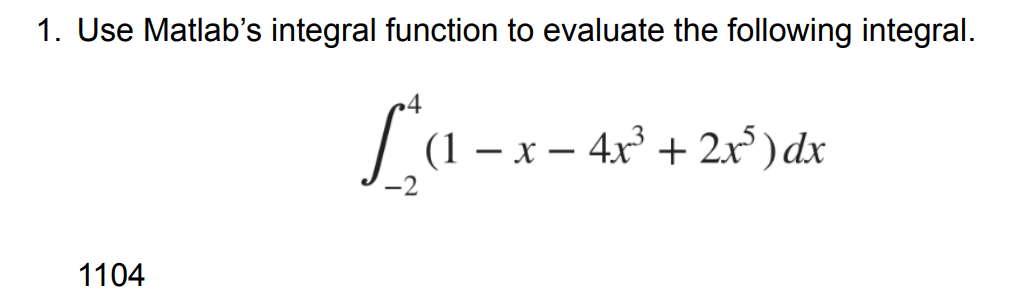

%Recap above 
%Question 1
f = @(x) 1 - x - 4*x.^3 + 2*x.^5;
def_int = integral(f, -2, 4); %lower limit, then upper
disp(['Definite integral = ', num2str(def_int)]);

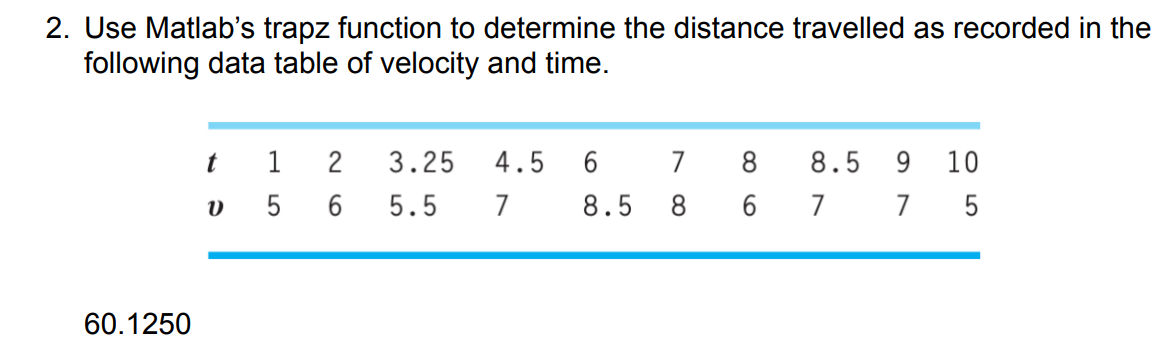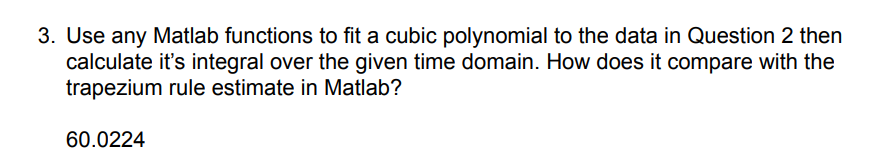

%Q2

%First write down the data points, then use trapz rule
t = [1 2 3.25 4.5 6 7 8 8.5 9 10];
v = [5 6 5.5 7 8.5 8 6 7 7 5];
trapezium_appl = trapz(t, v);
disp(['Trapezium Applied = ', num2str(trapezium_appl)]);

Trapezium Applied = 60.125


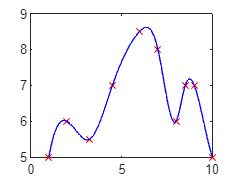



%Good question, first you plot the data points and follow simple
%interpolation algorithm for splines to see how it fits, and how it should
%fit. Then you comment the plotting and start with integral calculation.
%Q3
%plot(t, v, 'xr');
%hold on;
%xfit = linspace(1, 10);
%yfit = spline(t, v, xfit);
%plot(xfit, yfit, '-b');



%For simplicity, convert x = t, y = v (ind, dependent variable) Use the
%matrix formula, remember to traspose y. Get coefficients. Once gotten,
%multiply them with a cubic equation as asked in the form of cubic with
%three powers of x and last coefficient value.
%Now finally you have J, integrate it over time domain (ending - start).
x = t;
y = v;

M = [
    x(1)^3 x(1)^2 x(1)^1 1; 
    x(2)^3 x(2)^2 x(2)^1 1;  
    x(3)^3 x(3)^2 x(3)^1 1; 
    x(4)^3 x(4)^2 x(4)^1 1; 
    x(5)^3 x(5)^2 x(5)^1 1; 
    x(6)^3 x(6)^2 x(6)^1 1; 
    x(7)^3 x(7)^2 x(7)^1 1;
    x(8)^3 x(8)^2 x(8)^1 1;
    x(9)^3 x(9)^2 x(9)^1 1;
    x(10)^3 x(10)^2 x(10)^1 1;
    ];

r = y';
a = M\r;

j = @(x) a(1)*x.^3 + a(2)*x.^2 + a(3)*x + a(4);

final_integral = integral(j, 1, 10);

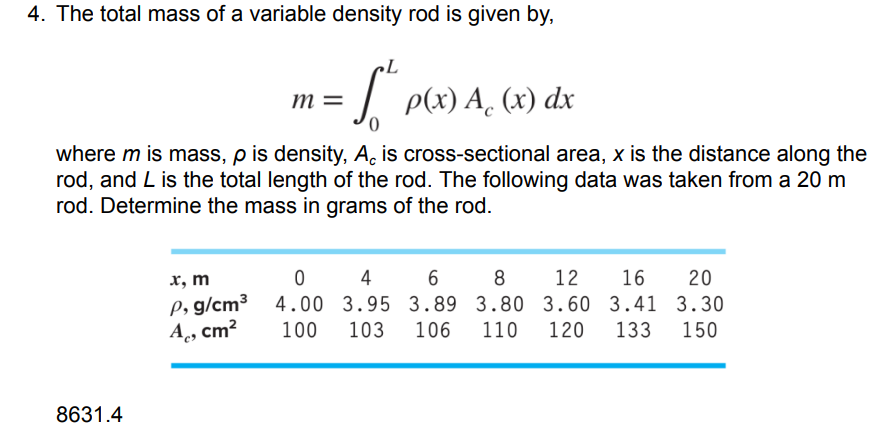

%Q4
clear;
%Get x, p, A as vectors. The equation is asking integral of p(X) times
%A(x), basically with given values we have to come up with p(x) with
%coefficients and A(x) with coeff. and then integrate them based on
%functions of x.
x = [0 4 6 8 12 16 20];
p = [4 3.95 3.89 3.8 3.6 3.41 3.3];
A = [100 103 106 110 120 133 150];

L = 20;

M = [
    x(1)^6 x(1)^5 x(1)^4 x(1)^3 x(1)^2 x(1)^1 1; 
    x(2)^6 x(2)^5 x(2)^4 x(2)^3 x(2)^2 x(2)^1 1;  
    x(3)^6 x(3)^5 x(3)^4 x(3)^3 x(3)^2 x(3)^1 1; 
    x(4)^6 x(4)^5 x(4)^4 x(4)^3 x(4)^2 x(4)^1 1; 
    x(5)^6 x(5)^5 x(5)^4 x(5)^3 x(5)^2 x(5)^1 1; 
    x(6)^6 x(6)^5 x(6)^4 x(6)^3 x(6)^2 x(6)^1 1; 
    x(7)^6 x(7)^5 x(7)^4 x(7)^3 x(7)^2 x(7)^1 1
    ];

%Same length vectors, and x used in both, just transpose both altogether
pc = M\p';
Ac = M\A';

%Remember j = integrand.
j = @(x) (pc(1)*x.^6 + pc(2)*x.^5 + pc(3)*x.^4 + pc(4)*x.^3 + pc(5)*x.^2 + pc(6)*x + pc(7)).*...
          (Ac(1)*x.^6 + Ac(2)*x.^5 + Ac(3)*x.^4 + Ac(4)*x.^3 + Ac(5)*x.^2 + Ac(6)*x + Ac(7));

% Use the integral function for numerical integration
R = integral(j, 0, L);

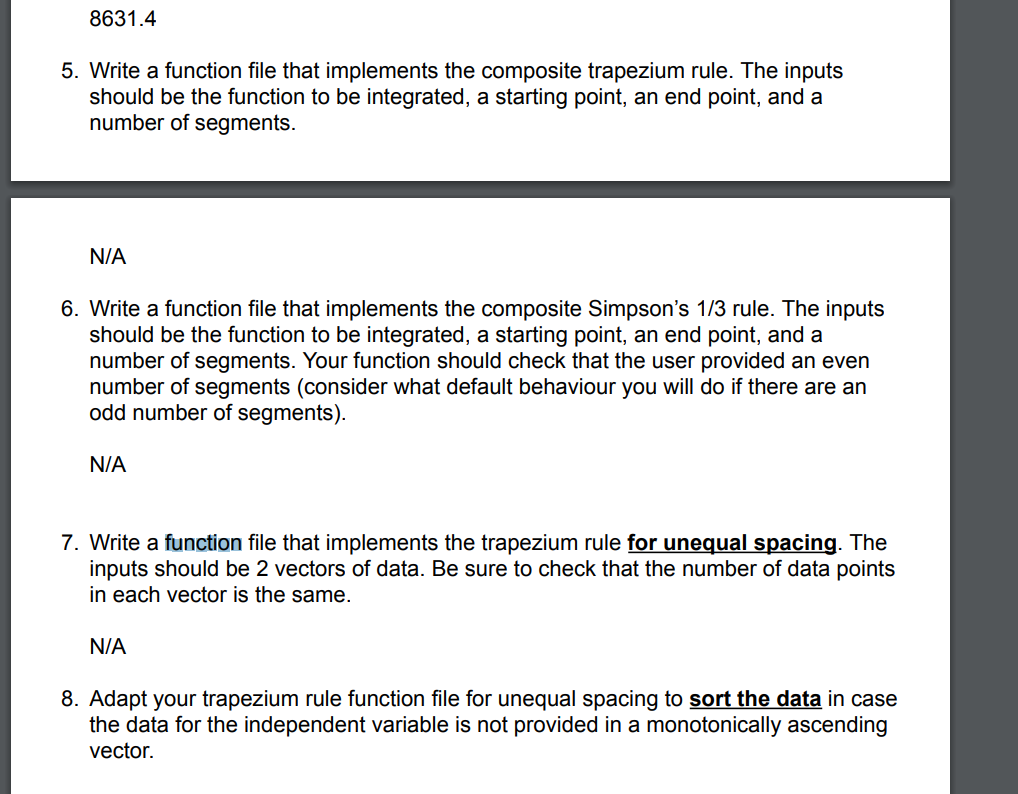

format long 
%l = @(x) -0.018*x.^3 + 0.1753*x.^2 + 0.0603*x + 4.8507;
%EXTRA PRECISION :
l = @(x) -0.018000930173303*x.^3 + 0.175315245196454*x.^2 + 0.060288508258602*x + 4.850657832944021;
a = 1;
b = 10;
n = 4;
J = double(CompTrapezium(l, a, b, n));
N = double(Simpson13(l, a, b, n));

function IE = CompTrapezium(fun, a, b, n) %Comp Trapezium WITH ERROR CALCULATION
    h = (b - a) / n;
    I = (fun(a) + fun(b)) / 2;
    for i = 1:n-1
        x = a + (i * h);
        I = I + fun(x); 
    end
    I = I * h; 
    syms x
    s = diff(fun, x , 2);
    F2avg = int(s, a, b) / (b - a);
    E = (-(b - a)/12) * h^2 * F2avg;
    IE = [I, E];
end


function IE = Simpson13(fun, a, b, n) %SIMPSON's with error calculation
    if mod(n, 2) == 0
        h = (b - a) / n;
        I = (fun(a) + fun(b));
        for i = 1:n-1
            x = a + (i * h);
            if mod(i, 2) == 0
                I = I + (2 * fun(x));
            else
                I = I + (4 * fun(x));
            end
        end
        I = I*((b-a)/(3*n));
        syms x
        s = diff(fun, x, 4);
        F2avg = int(s, x);
        E = (-(b - a).^5 / (180 .* n.^4)) .* F2avg;
        %E = (-1 / 1440) * h.^5 * s
        IE = [I, E];
    else
        error('Number of segments (n) must be even for Simpson''s 1/3 rule.');
    end
end